**Introduction:**

Subsequently, reflecting the conversion of the network in the 1970's to support various hydrological studies, an attempt was made to investigate more complex, large-scale relationships between the isotope abundance and environmental factors. One model commonly incorporated to explain the global heavy water isotope precipitation is the Rayleigh fractionation [1], which is dependent on the ambient temperature. Consequently, some form of correlation between average annual temperature and isotope fractionation can be expected and it is demonstrated here how to visualise the same. Furthermore, a 2007 article by Lee et al. [2] reports the increase of Oxygen-18 ratio with annual mean temperature to be approximately linear for regions with average annual temperatures of 15° or less. Following this information, the project aims to determine linear equations describing the temperature/isotope fraction correlation for all three isotopes and evaluate their goodness of fit. The structure of the computational methods chosen to achieve this are designed to be easily adaptable for other potentially influential factors like altidue or geographical coordinates.   

[1] - Carol Kendall and Eric A. Caldwell, [Isotope Tracers in Catchment Hydrology](http://wwwrcamnl.wr.usgs.gov/isoig/isopubs/itchinfo.html) (1998), (Eds.)Elsevier Science B.V., Amsterdam. pp. 51-86.

[2] - J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007

[3] - World Bank Group Climate Change Knowledge Portal [http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)

[4] -  *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *

[5] - GNIP homepage [http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html](http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html)

** 2. Investigation of a Correlation between Temperature and Isotope Precipitation**

The first hurdle to conquer when investigating world-wide trends is managing large amounts of data with concise coding. To be able to work with statistically relevant sample sizes, almost the entire GNIP database as well as temperature records from the World Bank Group Climate Change Knowledge Portal were downloaded by country and now have to be imported into the workspace:

%The following path has to be adjusted for each user!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/MakingMaps/';

%Load all .xls files (the climate data) into one cell array
AATdata=loadfiles(source_dir,'*.xls');

%Load all GNIP .xlsx files (the isotope data) into one cell array
Isotopedata=loadfiles(source_dir,'*xlsx');

The function 'loadfiles' was written specifically for the purpose of loading a large number of excel tables into Matlab. It is defined at the end of the script as follows:

function loadedfiles=loadfiles(filepath, filextension)  %The complete file path and file extension are needed
    
source_files = dir(fullfile(filepath, filextension));   %The fullfile function merges file name fragments and the dir function lists all files the thereby specified folder which have the given extension
loadedfiles=cell(size(source_files));                   %Precreate an empty cell array for all files to be loaded
      
    for i = 1:length(source_files)
      loadedfiles{i} = readtable(fullfile(filepath, source_files(i).name));  %One by one, every excel file identified above is loaded into Matlab using the readtable function
    end
end

Each cell in either of the cell arrays 'Isotopedata' and 'AATdata' correponds to the GNIP data or climate data for one country.

A scatterplot of the heavy isotope fraction against temperature is a good measure to get a first impression of the nature of correlation (if there is any at all). To produce such a plot, averages over the isotope and temperature values had to be calculated for each country. Although only calculations for median values are represented here, mean values were calculated with the same method: 

%Calculate the medians for H2, H3, O18 and temperature across a country for all datasets
means=zeros(size(Isotopedata,1),4); %creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};     %The for loop will repeat the data collection for every country               
   tempdata=AATdata{i,1};
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   %Calculates medians for the isotopes ignoring NaN values
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    %Calculates medians for temperatures ignoring NaN values
   
end  

According to G Torri et al. [4] , the abundance of heavy isotopes is usually measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of the heavy isotope to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\mathrm{ppm}$$
 

The H3 abundance was not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D had to be calculated before proceeding:

vsmow=1.85*10^-11;   %Given in ppm for tritium
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;

Scatterplots could now be produced for all three isotopes: 

%Exemplary code to plot scatterplots of isotope concentration in precipitation vs temperature

figure(1);
scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');    %This labels the graph with all relevant information
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

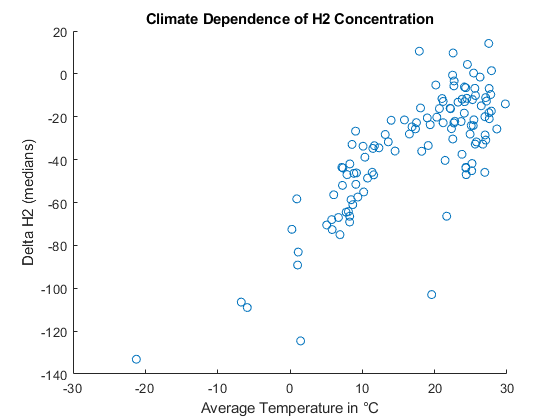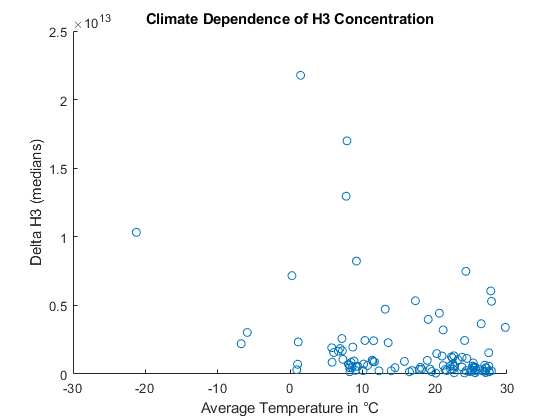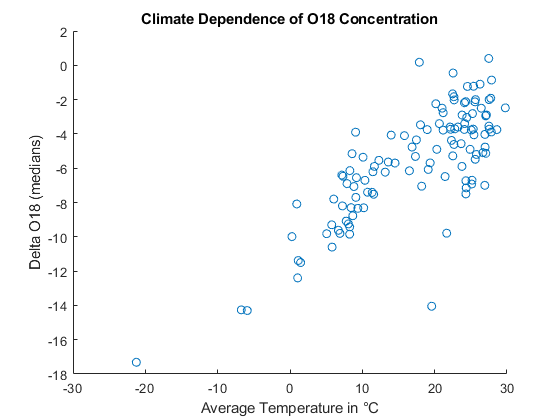

The scatterplots make evident that while there appears to be a roughly linear relationship for H2 and O18, the H3 abundance in precipitation can not easily be related to temperature. It is also visible that the scattering becomes significantly more random for high temperatures, which agrees with reference article by Lee et al. [2]. They give a cutoff temperature of 15°C, so in order to fit a regression line to the data, only datapoints with temperatures below 15°C were consider for the next step of the analysis:

%Collect all median values for temperatures below 15°C only

n=1;
for k=1:length(medians)
    if medians(k,4)<=15
        behavedmedians(n,:)=medians(k,:);    %Medians that theoretically follow the relationship are added to a new array
        n=n+1;
    end
end

Lastly, the curve fitting toolbox was utilised to fit a first degree polynomial (i.e. a linear regression line) to the selected data range. This happened within a special function which not only fits a regression line to one dataset against temperature, but that accepts several input arrays as possible y-values, compares the goodness of fit for each and only returns the fitted curve with the best fit. The goodness of fit was assesed by comparison of the coefficient of determination R², which is the proportion of variance in the dependent variable that is explained by the independent variable, hence a high R² indicates a good fit.

function bestfit=fitfunction(X,varargin)    %fitfunction accepts a variable number of input arguments
    
    gof=zeros(length(varargin),1);          %Create an empty array to hold the coefficients of determination for later comparison
    
    for i=1:length(varargin)                %For every given possible y-value dataset...
        [~, gofi]=fit(X,varargin{i},'poly1');   %...a 1st degree polynomial is fitted...
        gof(i)=gofi.rsquare;                %... and the coeffitient of determination is retained
    end
    
    [bestgof, gofnb]=max(gof);              %The y-value dataset which provides the highest R² (--> the best fit) is determined
    coefficients=fit(X,varargin{gofnb},'poly1'); %Calculate the coefficients for the linear equation describing the best fit
    
    bestfit={coefficients,bestgof,gofnb+1};   %The function outputs the best fit coefficients, the corresponding R² and the number of the input variable that provides the best fit
end

This function was simultaneously used on the mean and median values for deuterium and oxygen-18 in the temperature range of interest:

BestFit=fitfunction(behavedmeans(:,4),behavedmeans(:,1),behavedmedians(:,1),behavedmeans(:,3),behavedmedians(:,3))

Which provided the following result:

`BestFit = 1×3 cell array`

`    {1×1 cfit}    {[0.8012]}    {[4]}`

`Coefficients = `

`     Linear model Poly1:`

`     Coefficients(x) = p1*x + p2`

`     Coefficients (with 95% confidence bounds):`

`       p1 =      0.4499  (0.3801, 0.5197)`

`       p2 =       -11.8  (-12.43, -11.16)`

This means the mean values of oxygen-18 most closely correlate to the mean annual temperature, so this graph was chosen for plotting:

figure(2);
plot(BestFit{1},behavedmeans(:,4), behavedmeans(:,3));      %Plot the linear regression line as determined before for the best fitting pair of datasets
xlabel('Average Annual Temperature in °C');                 %Label the graph appropriately
ylabel('Delta D O18 (means)');
title('Best Fitting Linear Regression Line: O18 (means)');

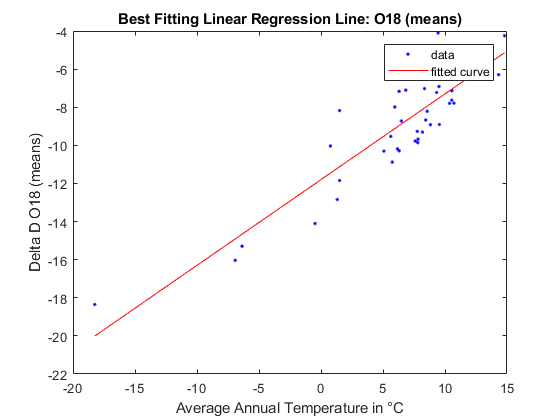

## **Critical Discussion of Results**

**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

 A linear relationship described by Delta D(O18) = 0.4499*T -11.8 was found as the best fit across all analysed data, where 80.12% of the variance in Delta D are confidently predicted by the temperature. This fit is good enough to succesfully validate a temperature dependence in the isotope fractionation for temperatures below 15°C, but in comparison with literature values [2], it is still relatively unprecise. Lee et al. observe a relationship of the form 0.69*T-14.49 with a coefficient of determination of 98%, quite different and with much less uncertainty than what was found here. The discrepancy most likely stems from the measures taken to simplify the analysis: 

- While the Isotope values are recorded at usually only a few locations per country, the average temperature is taken for the whole country. An alternative option would be to receive the temperature data from the GNIP datafiles for the specific locations of measurement, but not all stations include air temperature in their datasets, which significantly reduces the available sample size. Furthermore is it by no means guarateed that the included air temperatures gives an acccurate account of the annual temperature, for example, one station in a hot climate might record the temperature in the colder hours of the morning and report the same average temperature as a station in a colder climate which takes measurements around the time when daily temperatures peak.

- The size of the countries is neglected and each one is summarised to one data point, which causes large errors for countries like the USA or Russia that potentially span several climate zones. For increased precision, data should be grouped in smaller geographic regions or by climate zone. Ideally, each station would be plotted against the local average temperature on it's own.

- The annual temperature is (with a few exceptions) averaged over 30 years between 1960 and 1990, while part of measurements are from more recent decades. Cimate change might have caused distortion in relationship under these conditions.

- Some countries have stations in locations that are allocated to a certain country in the GNIP database and therefore went into the calculations for this country, although they geographically lie in an entirely different climate zone (for example: Saint Helena in the South Altlantic Ocean provides misleading measurements for a 'UK climate')

It is worth noting that with the shown procedures, an analysis of the deuterium precipitation with temperature gives a regression line with comparable precision (78.67%). Only tritium does not display such a correlation. The most probable explanation stands as follows: When considering the relative amounts of heavy isotopes against normal water isotopes, tritium is less abundant than deuterium or oxygen-18 by several orders of magnitude ($R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\text{ppm}$ for tritium compared to $R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$ for deuterium). The smallest inaccuracy, sample contamination or human made or natural, temperature independent nuclear activity heavily disturbs a natural tririum distribution. The GNIP itselfs [5] points out that for several stations the tritium values substantially exceed the expected figures, most likely due to local technigenic tritium or significant contamination of the sample collection.

The last question remaining is, why does a temperature dependence occur at all? To understand this, one must consider the Rayleigh fractionation [1]: it describes the change in isotope ratios of an open system subject to fractional distillation, for example when the vapour phase condenses in clouds and leaves the system as rain. Heavy isotopes like deuterium and oxygen-18 tend to leave the vapour phase earlier/at higher temperatures than normal isotopes due to their higher mass, they have a higher boiling point. Consequently, cold air masses are less likely to hold evaporated heavy isotopes, they only evaporate in warm conditions and rain out when the air cools down. However, as Lee et. al. [2] point out, while being the most widely applied explanation for global isotope distributions, Rayleigh fractionation does not explain all trends. As apparent in the here produced scatterplots, the effect of the high mass isotopes on solubility in air becomes negligible for high temperatures, above 15°C a slightly higher boiling point for heavy isotopes is irrelevant. Instead, other factors like surface fluxes play a much bigger role in the saturation of heavy isotopes in precipitation. It is therefore of special interest to conduct analysis of the isotope fractionation of hot zones like the tropics, which is explored in section 3 of this report.

## Conclusions and Future Work

**2) Investigation of a Correlation between Temperature and Isotope Precipitation**

In conclusion it can be said that the average local temperature does influence the global isotope distribution to a significant degree, it is therefore definitely worth studying the same. The present analysis is, however, only suitable to validate general trends, the numerical results do not have a statistical certainty high enough to be considered reliable yet. Future efforts based on this work could include a finer geographic separation of the GNIP stations so that the mean isotope values and temperatures are calculated for smaller areas. In fact, work towards this goal has already begun (see full code file), but is not completed yet. However, as influential as temperature has proven to be, the established computational methodology can easily adapted to investigate possible correlations between other environmental factors too, for example altitude, latitude or vapour pressure. Overall, Matlab has proven to be a very suitable tool for this type of analysis.

The next step in the processing of global isotope data is visualising the distribution with the mapping toolbox, which has also been partially attempted already (see full code file). A first goal in this section would be to mark all GNIP stations on a global projection and indicate trends in average isotope precipitation with different colours. Initially, the stations would be represented by points, but Matlab also facilitates the production of texture maps with more fluid transitions. Apart from heavy isotope fractions, the previously named possible influential factors like temperature or altitude can be depicted in the same way. The final step would be to compute geolocated grids containing the relative differences between isotope fraction and influential variable and project these on a global map. This way, more regions of interest like the tropics where commonly accepted relationships do not hold can easily be found and graphically represented. 